**Input Data Initialization**

First we initialize input data and create a scatter plot from them to verify that the problem is indeed linearly separable.

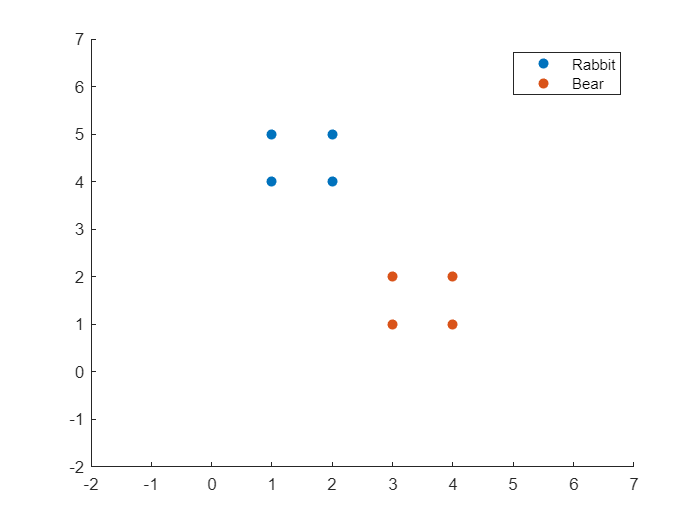

% Input data init
class_zero = [[1; 4; 0], [1; 5; 0], [2; 4; 0], [2; 5; 0]];
class_one = [[3; 1; 1], [3; 2; 1], [4; 1; 1], [4; 2; 1]];
% Display scatter chart 
scatter(class_zero(1, :), class_zero(2, :), "filled", 'DisplayName','Rabbit');
hold on
scatter(class_one(1, :), class_one(2, :), "filled", 'DisplayName', 'Bear');
axis([-2, 7, -2, 7]);
legend
hold off

**Network Construction and Training (I & II)**

For this problem a single-neuron perceptron will suffice. Therefore we randomly initialize a weight and bias for our perceptron.

First we draw weights and biases from a normal distribution:

% draw weights and biases from N(0, 1)
bias = randn;
weights = randn([2 1]);
fprintf('Starting weights: [%f, %f]\n', weights(1), weights(2));

Starting weights: [-0.476153, 0.862022]


fprintf('Starting bias: %f', bias);

Starting bias: 0.183689

% using hardlim as activation

Now we will use the Perceptron Rule to train our network:

all_data_points = [class_zero class_one];
epoch = 0;
num_tests = 8;
accuracy = 0.0;
% Training loop
% Culmination condition, either 50 epochs (assume non-convergent) or
% perfect accuracy
while accuracy ~= 1.0 && epoch < 50
    passes = 0;
    fprintf('Start of epoch %d \n', epoch);
    for point=all_data_points
        xy = [point(1); point(2)];
        a = hardlim(weights'*xy + bias);
        t = point(3);
        e = t-a;
        % if zero error: correct classification
        if e == 0
            passes = passes + 1;
        end
        weights = weights + e*xy;
        bias = bias + e;
    end
    accuracy = passes / num_tests;
    fprintf('Accuracy at the end of epoch %d: %f', epoch, accuracy);
    epoch = epoch + 1;
end

Start of epoch 0 


Accuracy at the end of epoch 0: 0.750000

Start of epoch 1 


Accuracy at the end of epoch 1: 1.000000

fprintf('Weights after training: [%f, %f]\n', weights(1), weights(2));

Weights after training: [1.523847, -2.137978]


fprintf('Bias after training: %f', bias);

Bias after training: 0.183689

We can now test the network to see if it can correctly classify all of the data points:

% Evaluation
passes = 0;
for point=all_data_points
    xy = [point(1); point(2)];
    a = hardlim(weights'*xy + bias);
    t = point(3);
    e = t-a;
    if e == 0
        passes = passes + 1;
    end
end
fprintf('Classified %d out of %d correctly.', passes, num_tests);

Classified 8 out of 8 correctly.

**Plotting the Classifier (I & II)**

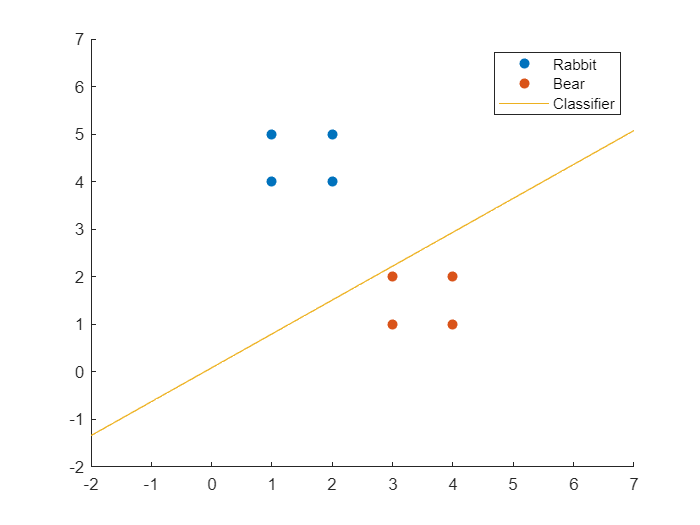

x = linspace(-2, 7);
y = (-weights(1)*x - bias)/weights(2);
scatter(class_zero(1, :), class_zero(2, :), "filled", 'DisplayName','Rabbit');
hold on
scatter(class_one(1, :), class_one(2, :), "filled", 'DisplayName', 'Bear');
hold on
plot(x, y, 'DisplayName', 'Classifier');
axis([-2, 7, -2, 7]);
legend
hold off

**Adding Additional Data Points to Ensure Robustness (III)**

Consider the two closest data points from either of the classes by measure of Euclidean distance. If we add two points, one from each class at either extreme of the section connecting these two points, the network should be robust. 

% calculate distance pairs and keep the one with the least distance
dmin = inf;
zero_min = [nan; nan];
one_min = [nan; nan];
for point0=class_zero
    for point1=class_one
        xy0 = [point0(1); point0(2)];
        xy1 = [point1(1); point1(2)];
        d = sqrt(sum((xy0 - xy1).^2));
        if dmin > d
            dmin = d;
            zero_min = xy0;
            one_min = xy1;
        end
    end
end

Next, we calculate the equation of the line passing through these two points and then generate two points randomly on this line in the interval between the minimally distant points and classify them by measure of their Euclidean distance from either of the points. We will now have an additional point added to each class that limits the freedom degree of the decision boundary in such a way that it cannot pass through any of the original input data points. It is assumed for simplicity that the line section between the minimally distant points is not perpendicular to the x-axis. 

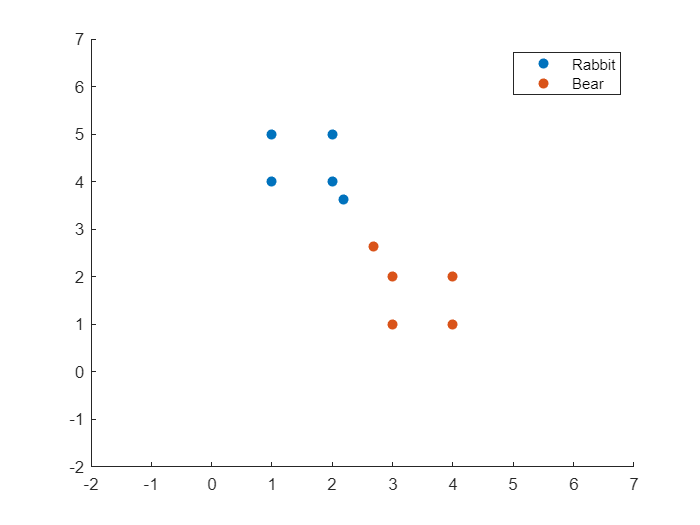

slope = (one_min(2) - zero_min(2))/(one_min(1) - zero_min(1));
x_min = min([zero_min(1), one_min(1)]);
x_max = max([zero_min(1), one_min(1)]);
x = x_min + (x_max - x_min)*rand([1 2]);
y = slope*(x-zero_min(1)) + zero_min(2);
% The point closest to xy0 is class zero and the other one is class one
xy = [x; y];
d0 = sqrt(sum((xy(:,1) - zero_min).^2));
d1 = sqrt(sum((xy(:,1) - one_min).^2));
if d0 < d1
    add_zero = [xy(:,1); 0];
    class_zero = [class_zero add_zero];
    add_one = [xy(:,2); 1];
    class_one = [class_one add_one];

else
    add_one = [xy(:,1); 1];
    class_one = [class_one add_one];
    add_zero = [xy(:,2); 0];
    class_zero = [class_zero add_zero];
end
% Generate scatter plot again
scatter(class_zero(1, :), class_zero(2, :), "filled", 'DisplayName','Rabbit');
hold on
scatter(class_one(1, :), class_one(2, :), "filled", 'DisplayName', 'Bear');
axis([-2, 7, -2, 7]);
legend
hold off

% Retrain the network with the new data and verify that the new decision
% boundary does not intersect with the any of the original data points
bias = randn;
weights = randn([2 1]);
fprintf('Starting weights: [%f, %f]\n', weights(1), weights(2));

Starting weights: [-0.334887, 0.552783]


fprintf('Starting bias: %f', bias);

Starting bias: -0.848709

% using hardlim as activation
all_data_points = [class_zero class_one];
epoch = 0;
num_tests = 10;
accuracy = 0.0;
% Training loop
while accuracy ~= 1.0 && epoch < 50
    passes = 0;
    fprintf('Start of epoch %d \n', epoch);
    for point=all_data_points
        xy = [point(1); point(2)];
        a = hardlim(weights'*xy + bias);
        t = point(3);
        e = t-a;
        if e == 0
            passes = passes + 1;
        end
        weights = weights + e*xy;
        bias = bias + e;
    end
    accuracy = passes / num_tests;
    fprintf('Accuracy at the end of epoch %d: %f', epoch, accuracy);
    epoch = epoch + 1;
end

Start of epoch 0 


Accuracy at the end of epoch 0: 0.700000

Start of epoch 1 


Accuracy at the end of epoch 1: 0.800000

Start of epoch 2 


Accuracy at the end of epoch 2: 0.800000

Start of epoch 3 


Accuracy at the end of epoch 3: 0.800000

Start of epoch 4 


Accuracy at the end of epoch 4: 1.000000

fprintf('Weights after training: [%f, %f]\n', weights(1), weights(2));

Weights after training: [8.038664, -5.194318]


fprintf('Bias after training: %f', bias);

Bias after training: 0.151291

% Evaluation
passes = 0;
for point=all_data_points
    xy = [point(1); point(2)];
    a = hardlim(weights'*xy + bias);
    t = point(3);
    e = t-a;
    if e == 0
        passes = passes + 1;
    end
end
fprintf('Classified %d out of %d correctly.', passes, num_tests);

Classified 10 out of 10 correctly.

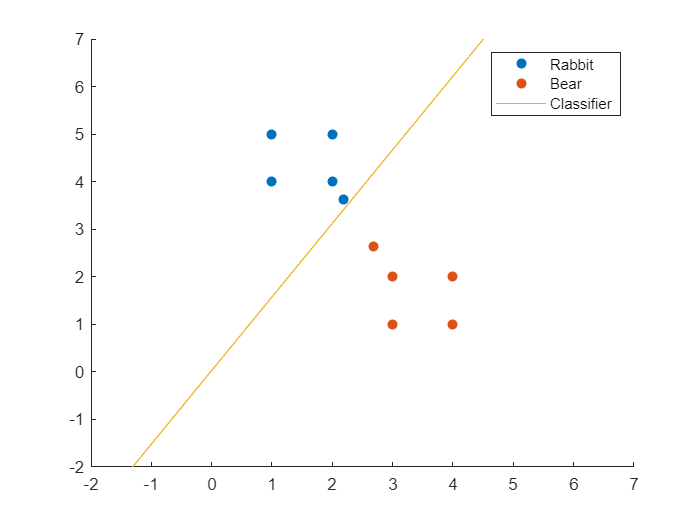

x = linspace(-2, 7);
y = (-weights(1)*x - bias)/weights(2);
scatter(class_zero(1, :), class_zero(2, :), "filled", 'DisplayName','Rabbit');
hold on
scatter(class_one(1, :), class_one(2, :), "filled", 'DisplayName', 'Bear');
hold on
plot(x, y, 'DisplayName', 'Classifier');
axis([-2, 7, -2, 7]);
legend
hold off